# **KUKA  Iiwa 7 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Clear the environment.

clc;
clear;
close all;

Load the KUKA Iiwa 7 rigid body tree (RBT) model.

robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "iiwa_link_ee_kuka"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

close all;
%% Construct voxel obstacle representation for STOMP planner
% Define the workspace (the voxel world limits). Depending on the robot's reach range.
Env_size = [-1, -1, -1; 2, 2, 2];  % [xmin, ymin, zmin] for 1st row, xyz-lengths for 2nd row
voxel_size = [0.02, 0.02, 0.02];  % unit: m
% Binary map: all free space initially, 
binary_world = zeros(Env_size(2, 1) / voxel_size(1), Env_size(2, 2) / voxel_size(2), Env_size(2, 3) / voxel_size(3));
% binary_world_offset = Env_size(1, :)./ voxel_size;

%% XYZ metric representation (in meter) for each voxel 
% !!!!Watch out for the useage of meshgrid:
% [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the 
% vectors x, y, and z. The grid represented by X, Y, and Z has size 
% length(y)-by-length(x)-by-length(z).
% The 3D coordinate is of the center of the voxels
[Xw, Yw, Zw] = meshgrid(Env_size(1, 1) + 0.5 * voxel_size(1) : voxel_size(1) : Env_size(1, 1) + Env_size(2, 1) - 0.5 * voxel_size(1), ...
       Env_size(1, 2) + 0.5 * voxel_size(2) : voxel_size(2) : Env_size(1, 2) + Env_size(2, 2) - 0.5 * voxel_size(2), ...
    Env_size(1, 3) + 0.5 * voxel_size(3) : voxel_size(3) : Env_size(1, 3) + Env_size(2, 3) - 0.5 * voxel_size(3));

%% Static obstacles
lbox = 0.08*2; % length of the cube
box_center = [0.15 0.3 0.6]; % (metric) world coordinates of the box center
aObs = collisionBox(lbox,lbox,lbox);  
aObs.Pose = trvec2tform(box_center);   


% Set static obstacles
world = {aObs}; % try adding more static obstacles aObs to dObs or create your own

%% Visulaization the obstacle
% for i=1: length(world)
%     show(world{i})
% end

%% voxelize the box obstacles
cube_metric = [box_center-lbox/2;
                lbox,lbox,lbox]; % [xmin, ymin, zmin] for 1st row, xyz-lengths for 2nd row
% range (lower and upper limits) of the cube voxel
% The number inside ceil is always positive
cube_voxel = [ceil((cube_metric(1, :)-Env_size(1,:))./voxel_size); ...
    ceil((cube_metric(1, :) + cube_metric(2, :)-Env_size(1,:))./voxel_size)];

% Update the cube occupancy in the voxel world
% First generate the 3D grid coordinates (x,y,z subcripts) of cube in the voxel world
[xc, yc, zc] = meshgrid(cube_voxel(1, 1):cube_voxel(2, 1), cube_voxel(1, 2):cube_voxel(2, 2), cube_voxel(1, 3):cube_voxel(2, 3));
% Set the corresponding voxel occupancy to 1, meaning occupied
binary_world(sub2ind([Env_size(2, 1) / voxel_size(1), Env_size(2, 2) / voxel_size(2), Env_size(2, 3) / voxel_size(3)], xc, yc, zc)) = 1;

% % plot the occupied voxel with a marker *
% plot3(xc(:), yc(:), zc(:), '*');
% % Or you can use the volumeViewer() from the Image Processing Toolbox to 
% % display the voxel_world in 3D. 
% volumeViewer(voxel_world);

%% construct signed Euclidean Distance for the voxel world
% Only approximation if the voxel is not a cube
voxel_world_sEDT = prod(voxel_size) ^ (1/3) * sEDT_3d(binary_world);


voxel_world.voxel_size = voxel_size;
voxel_world.voxel = binary_world;
% voxel_world.offset =  binary_world_offset;
voxel_world.world_size = size(binary_world);
voxel_world.Env_size = Env_size; % in metric 
voxel_world.sEDT =  voxel_world_sEDT;


Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

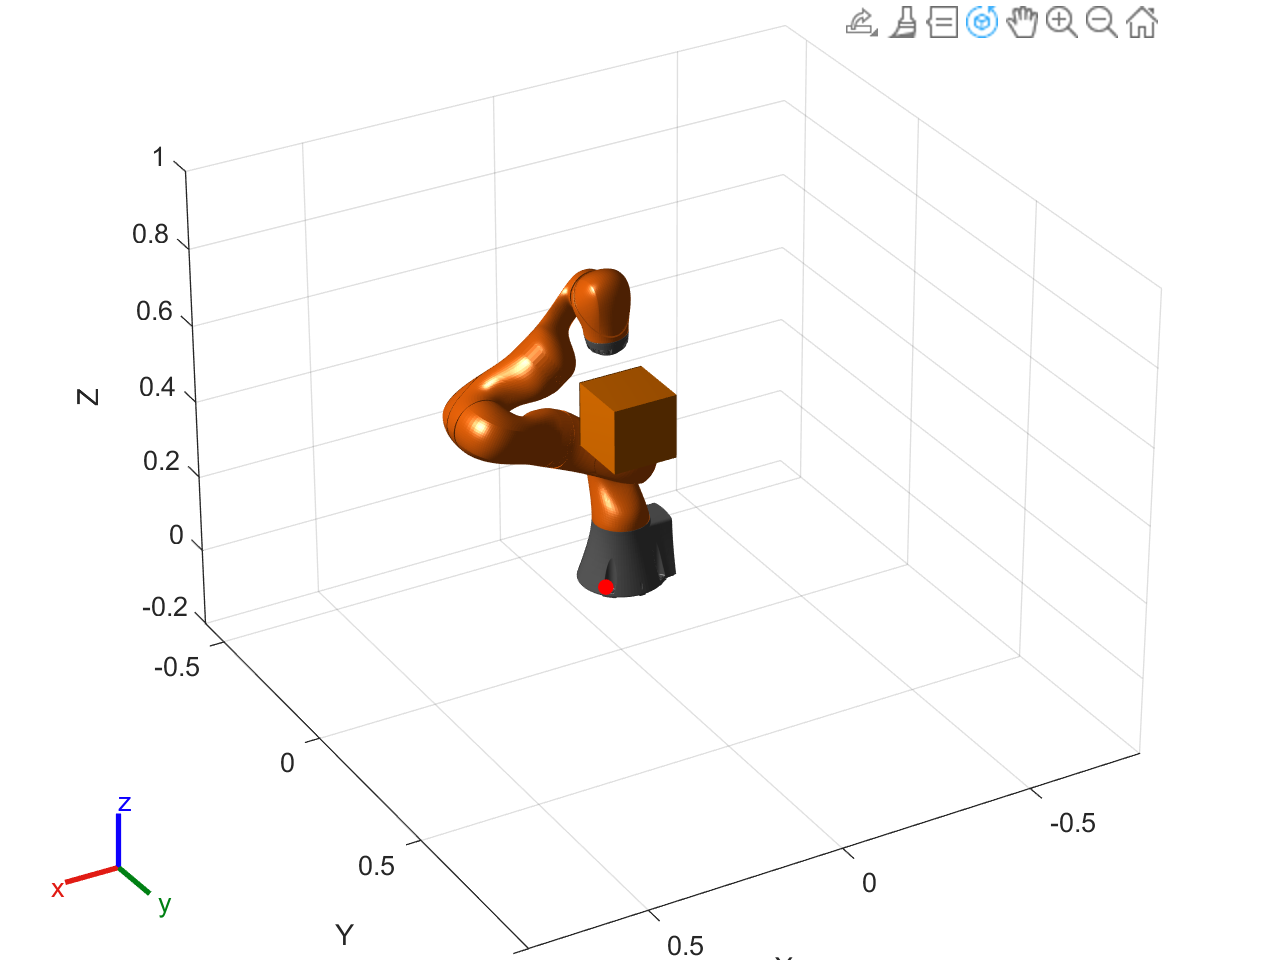

x0 = [currentRobotJConfig', zeros(1,numJoints)];

% Visualize the obstacles and robot manipulator

% Initial visualizer
positions = x0(1:numJoints)';

% figure(): The 1st and 2nd number is the pixel position of the figure relative to
% the monitor display. The 3rd and 4th number are the width and height of
% the figure.
hgif = figure('Position', [375 446 641 480]);
% 'PreservePlot'= True: The function does not overwrite previous plots displayed by calling show. 
% This setting functions similarly to hold on for a standard MATLAB® figure, 
% but is limited to robot body frames. When you specify this argument as 
% false, the function overwrites previous plots of the robot.
% 'Frames': Display body frames
ax1 = show(robot, positions(:,1),'PreservePlot', false, 'Frames', 'off');
% view(az,el) sets the azimuth and elevation angles of the camera's line of
% sight for the current axes
view(150,29)
hold on
% set the x,y,z, data limits of the figure
axis([-0.8 0.8 -0.6 1.0 -0.2 1.0]);
% plot the final position
plot3(poseFinal(1), poseFinal(2), poseFinal(3),'r.','MarkerSize',20)

% Visualize collision world specified in previous scripts
for i=1:numel(world)
    [~,pObj] = show(world{i});
    pObj.LineStyle = 'none';
end

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

历时 7.126539 秒。


Qtheta = 154.7822

RAR = 10.5471

历时 7.186072 秒。


Qtheta = 108.5924

RAR = 10.5517

历时 6.907021 秒。


Qtheta = 80.2168

RAR = 10.5562

历时 7.052275 秒。


Qtheta = 50.7271

RAR = 10.5589

历时 6.987906 秒。


Qtheta = 26.9711

RAR = 10.5608

历时 6.941391 秒。


Qtheta = 19.0293

RAR = 10.5615

历时 6.882971 秒。


Qtheta = 16.2466

RAR = 10.5590

历时 6.962883 秒。


Qtheta = 13.9931

RAR = 10.5592

历时 7.365191 秒。


Qtheta = 12.6985

RAR = 10.5574

历时 7.169348 秒。


Qtheta = 13.5312

RAR = 10.5565

历时 6.982824 秒。


Qtheta = 11.9260

RAR = 10.5540

历时 7.131274 秒。


Qtheta = 11.3066

RAR = 10.5574

历时 7.087100 秒。


Qtheta = 10.9419

RAR = 10.5606

历时 6.979935 秒。


Qtheta = 10.5611

RAR = 10.5611

历时 7.142039 秒。


Qtheta = 10.5600

RAR = 10.5600

STOMP Finished.


isTrajectoryInCollision = logical
   0


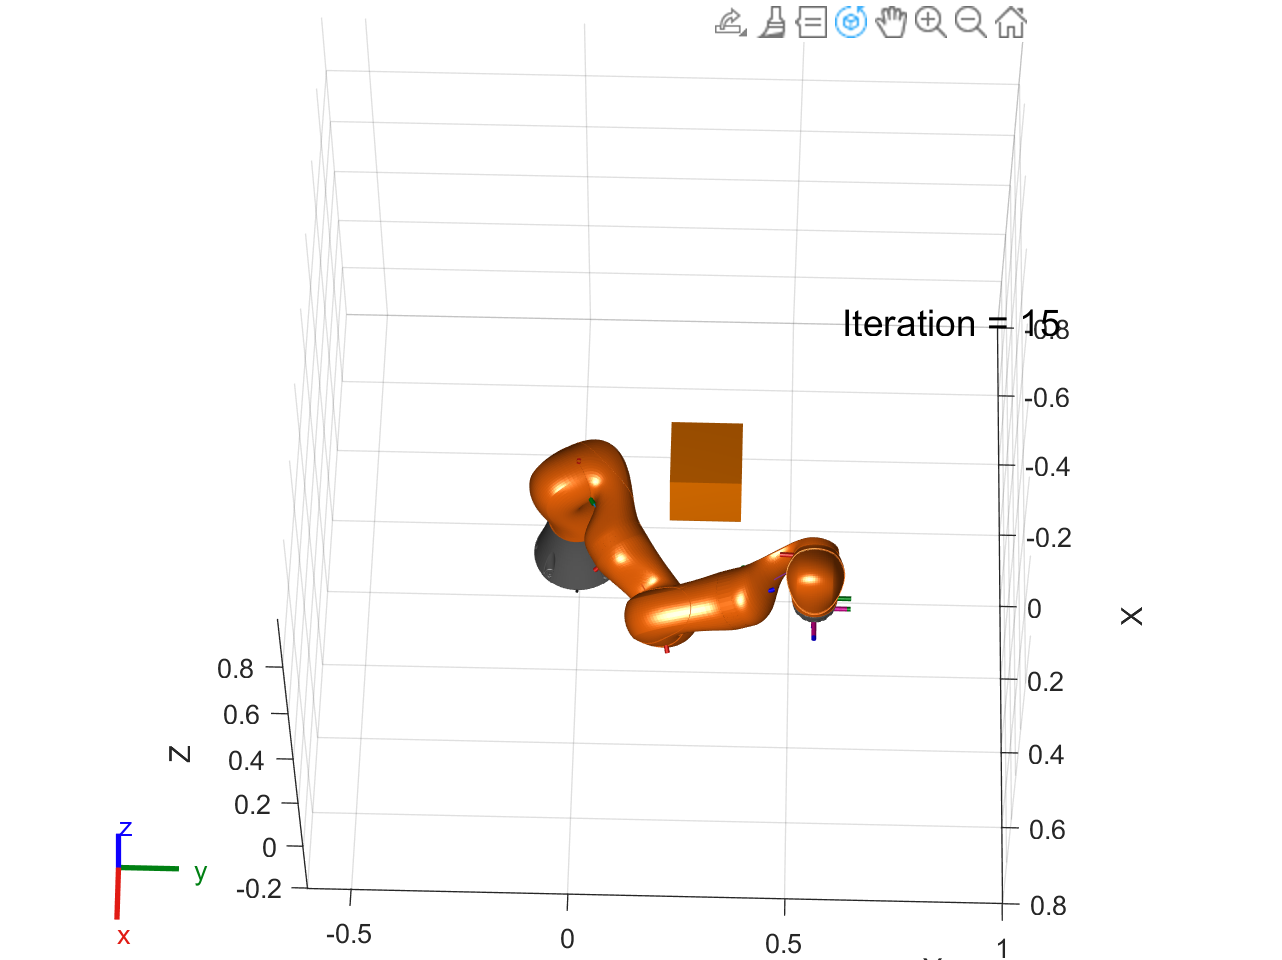

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.